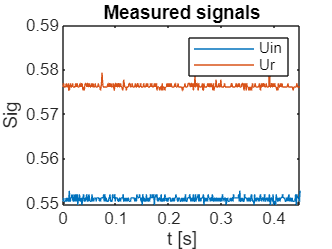

folder = "1Hz\fs1000\";

filenameLRs = folder+"LRs.csv";
filenameLRs_sig = folder+"LRs_sig.csv";
% filenameLRp = folder+"LRp.csv";
% filenameLRp_sig = folder+"LRp_sig.csv";
% filenameCRs = folder+"CRs.csv";
% filenameCRs_sig = folder+"CRs_sig.csv";
% filenameCRp = folder+"CRp.csv";
% filenameCRp_sig = folder+"CRp_sig.csv";


% LR parallel
T = readmatrix(filenameLRs);
T_sig = readmatrix(filenameLRs_sig);
fs = T(1,1);

% Process the signals with MATLAB
Uin = T_sig(:,1);
Ur = T_sig(:,2);
t = [0:1/fs:length(Uin)*1/fs-1/fs];

figure()
plot(t,Uin,t,Ur);
title('Measured signals');
xlabel('t [s]')
ylabel('Sig');
legend('Uin','Ur')


f1 = T(1,2);
f2 = T(1,5);
R1 = abs(T(:,3));
C1 = abs(T(:,4));
R2 = abs(T(:,6));
C2 = abs(T(:,7));